# Mean Gradient Plot

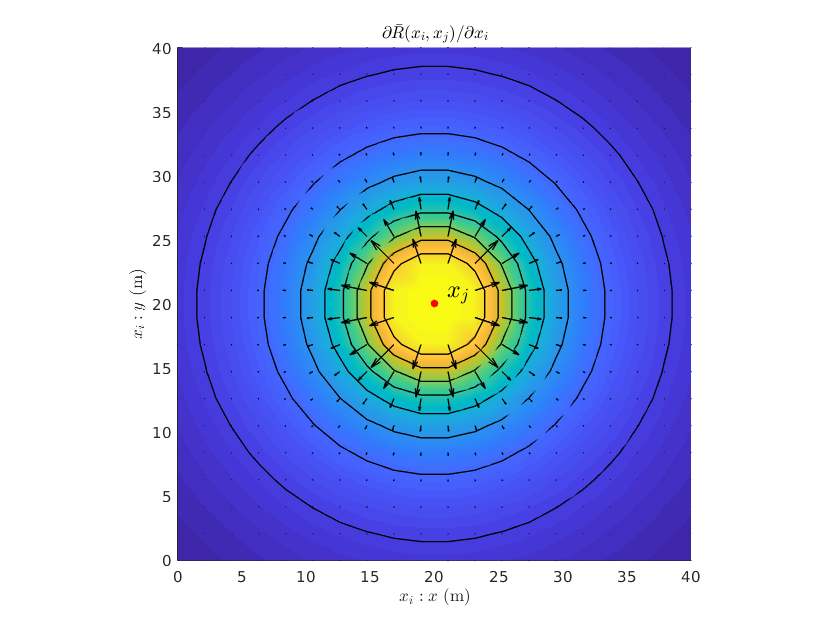

sample_count = 20;

xj = [20 20]';

xspace = linspace(0, 40, sample_count);
[x, y] = meshgrid(xspace, xspace);
x = x(:);
y = y(:);

derivative = zeros(2,length(x));
rate = zeros(length(x),1);
for i = 1:length(x)
  xi = [x(i) y(i)]';
  [rate(i), ~] = stochastic_channel(norm(xi - xj));
  derivative(:,i) = channel_derivative(xi, xj, 1, 'mean');
end

figure(1);clf;hold on;
surf(reshape(x, sample_count*ones(1,2)),...
     reshape(y, sample_count*ones(1,2)),...
     reshape(rate, sample_count*ones(1,2)),...
     'FaceColor', 'interp', 'EdgeColor', 'none');
contour3(reshape(x, sample_count*ones(1,2)),...
         reshape(y, sample_count*ones(1,2)),...
         reshape(rate, sample_count*ones(1,2)),...
         'Color', 'k', 'LineWidth', 1);
quiver3(x, y, rate, derivative(1,:)', derivative(2,:)', zeros(length(x),1),...
        'Color', 'k', 'LineWidth', 1)
h = get(gca,'DataAspectRatio');
set(gca,'DataAspectRatio',[1 1 1/h(1)]);
xlabel('$x_i : x$ (m)', 'Interpreter', 'latex', 'FontSize', 18);
ylabel('$x_i : y$ (m)', 'Interpreter', 'latex', 'FontSize', 18);
plot3(xj(1), xj(2), max(rate), 'r.', 'MarkerSize', 20);
text(xj(1)+1, xj(2)+1, max(rate), '$x_j$', 'FontSize', 18,...
     'Interpreter', 'latex')
title('$\partial \bar{R}(x_i,x_j) / \partial x_i$', 'Interpreter', 'latex',...
      'FontSize', 18);

# Variance Gradient Plot

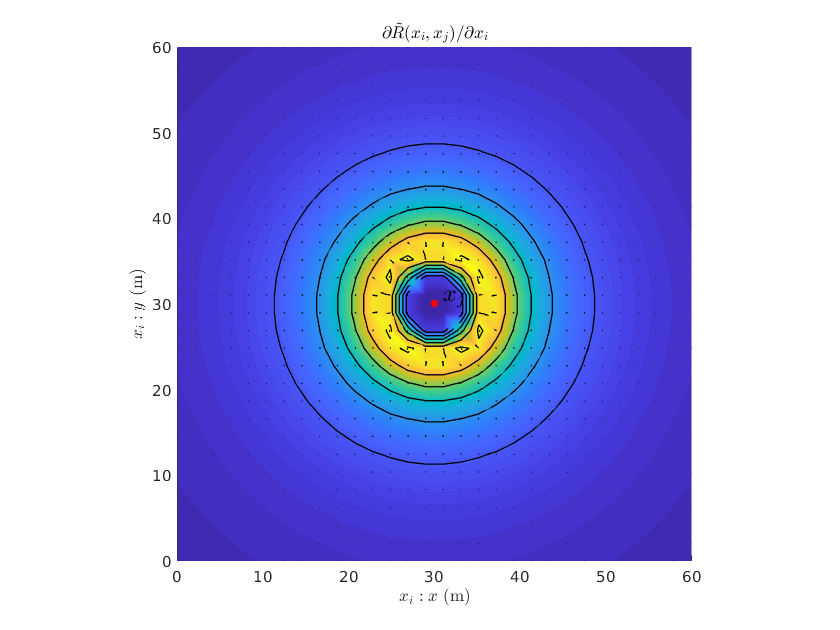

sample_count = 30;

xj = [30 30]';

xspace = linspace(0, 2*max(xj), sample_count);
[x, y] = meshgrid(xspace, xspace);
x = x(:);
y = y(:);

derivative = zeros(2,length(x));
var = zeros(length(x),1);
for i = 1:length(x)
  xi = [x(i) y(i)]';
  [~, var(i)] = stochastic_channel(norm(xi - xj));
  derivative(:,i) = channel_derivative(xi, xj, 1, 'var');
end

figure(1);clf;hold on;
surf(reshape(x, sample_count*ones(1,2)),...
     reshape(y, sample_count*ones(1,2)),...
     reshape(var, sample_count*ones(1,2)),...
     'FaceColor', 'interp', 'EdgeColor', 'none');
contour3(reshape(x, sample_count*ones(1,2)),...
         reshape(y, sample_count*ones(1,2)),...
         reshape(var, sample_count*ones(1,2)),...
         'Color', 'k', 'LineWidth', 1);
quiver3(x, y, var, derivative(1,:)', derivative(2,:)', zeros(length(x),1),...
        'Color', 'k', 'LineWidth', 1)
h = get(gca,'DataAspectRatio');
set(gca,'DataAspectRatio',[1 1 1/h(1)]);
xlabel('$x_i : x$ (m)', 'Interpreter', 'latex', 'FontSize', 18);
ylabel('$x_i : y$ (m)', 'Interpreter', 'latex', 'FontSize', 18);
plot3(xj(1), xj(2), max(var), 'r.', 'MarkerSize', 20);
text(xj(1)+1, xj(2)+1, max(var), '$x_j$', 'FontSize', 18,...
     'Interpreter', 'latex')
title('$\partial \tilde{R}(x_i,x_j) / \partial x_i$', 'Interpreter', 'latex',...
      'FontSize', 18);

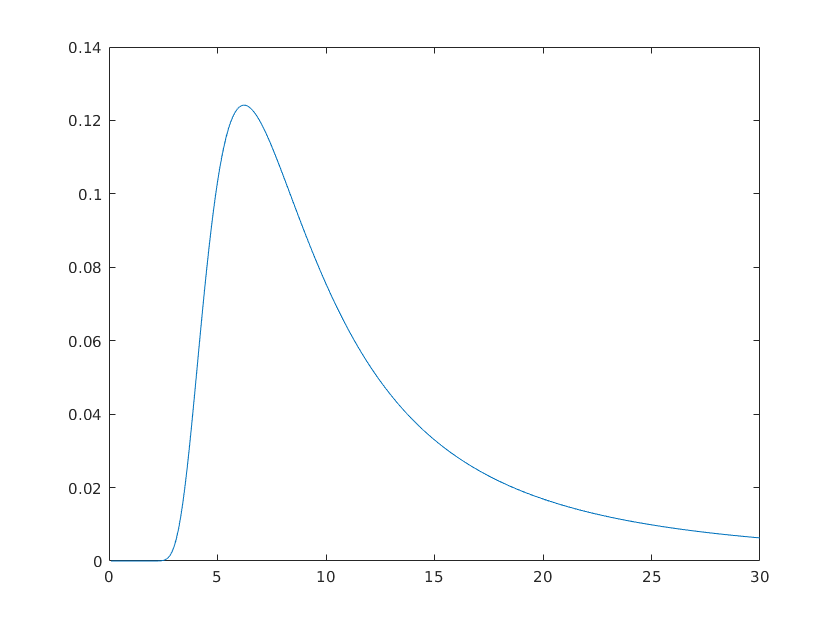

[~, var] = stochastic_channel(0:0.1:30);
figure(2);clf;
plot(0:0.1:30, var)